% system parameters
A = [-0.0085 0 0.0085 ; 0 -0.00195 0.0084; 0.0085 0.0084 -0.0169]

A =    -0.0085         0    0.0085
         0   -0.0019    0.0084
    0.0085    0.0084   -0.0169


B = [0.0065 0 ; 0 0.0065;0 0]

B =     0.0065         0
         0    0.0065
         0         0


C = [1 0 0;0 1 0;0 0 1]

C =      1     0     0
     0     1     0
     0     0     1


D = zeros(3,2)

D =      0     0
     0     0
     0     0



Bd =0;%a v b
Dd = 0;%gamma

Ef = [zeros(3,1), B]

Ef =          0    0.0065         0
         0         0    0.0065
         0         0         0


Ff =[C,zeros(3,1)] 

Ff =      1     0     0     0
     0     1     0     0
     0     0     1     0


% calculation s , Hos , Hus , Hfs , Hds 
Hos = obsv(A,C)

Hos =     1.0000         0         0
         0    1.0000         0
         0         0    1.0000
   -0.0085         0    0.0085
         0   -0.0019    0.0084
    0.0085    0.0084   -0.0169
    0.0001    0.0001   -0.0002
    0.0001    0.0001   -0.0002
   -0.0002   -0.0002    0.0004


R_Hos = rank(Hos)

R_Hos = 3

R_C = rank(C)

R_C = 3


s_min = R_Hos / R_C

s_min = 1

s_max = R_Hos + R_C-1

s_max = 5


s = 1;
Hos = [C ; C*A]

Hos =     1.0000         0         0
         0    1.0000         0
         0         0    1.0000
   -0.0085         0    0.0085
         0   -0.0019    0.0084
    0.0085    0.0084   -0.0169


Hus = [D zeros(3,2) ; C*B D]

Hus =          0         0         0         0
         0         0         0         0
         0         0         0         0
    0.0065         0         0         0
         0    0.0065         0         0
         0         0         0         0


Hfs = [Ff zeros(3,2) ; C*Ef Ef]

Hfs =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0    0.0065         0         0    0.0065         0
         0         0    0.0065         0         0    0.0065
         0         0         0         0         0         0



% PDD check
R1 = rank([Hos Hfs])

R1 = 6

R2 = rank([Hos])

R2 = 3

if R1 > R2
    display('PDD is ok')
else
    display('PDD is not ok')
end

PDD is ok



% calculation of parity vector
[a,b,c] = svd(Hos);
NB = a(:,length(a))';
[ps,J] = eig(NB*NB',NB*(Hfs*Hfs')*NB');
Vs = ps*NB

Vs =    -0.4106   -0.4059    0.8165    0.0052    0.0038   48.3169



% Vs = null(Hos');
% Vs = Vs'

norm(Vs*Hos)

ans = 1.3597e-16

norm(Vs*Hus)

ans = 4.2033e-05

norm(Vs*Hfs)

ans = 1

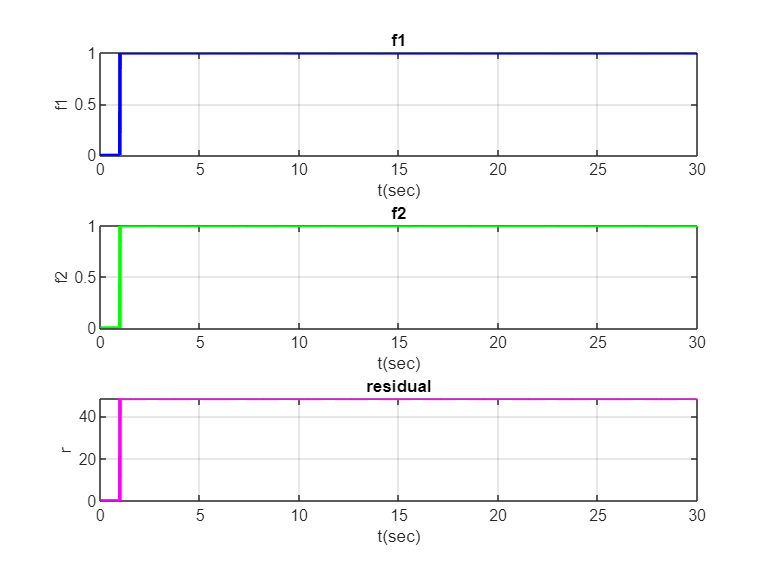


% time and amplitude of faults and disturbance 
f1 = [0 20 0 0 0 15 0 0 0 0];
f2 = [0 0 0 10 0 0 0 15 0 0];

sim('parity1',30);

figure (1)
subplot(311); 
plot(t,fd(:,1),'b','LineWidth',2), xlabel('t(sec)'), ylabel('f1'), title('f1'), grid
subplot(312); 
plot(t,fd(:,4),'g','LineWidth',2), xlabel('t(sec)'), ylabel('f2'), title('f2'), grid
subplot(313); 
plot(t,residual,'m','LineWidth',2), xlabel('t(sec)'), ylabel('r'), title('residual'), grid